a = 1 + mod(256, 3);

% Load the audio file
[y, Fs] = audioread("flute2.wav");

N = length(y); % Length of the signal
Y = fft(y); % Compute the FFT
frequencies = Fs * ((0:N-1) / N); % Frequency axis

% Calculate the magnitude of the spectrum
magnitude = abs(Y);

% Find the index of the peak frequency (excluding DC component)
[~, idx] = max(magnitude(2:end));

% Find the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(idx);

% Display the fundamental frequency
fprintf('Fundamental Frequency: %.2f Hz\n', fundamental_frequency);

Fundamental Frequency: 524.03 Hz


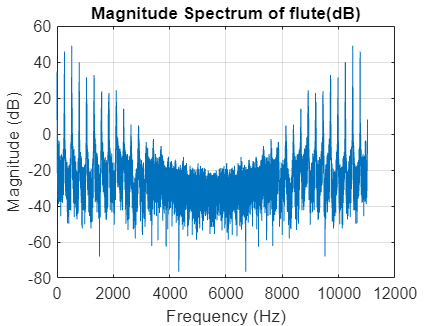



magnitude_dB = 20 * log10(magnitude);
plot(frequencies, magnitude_dB);
title('Magnitude Spectrum of flute(dB)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

a = 1 + mod(256, 3);

% Load the audio file
[y, Fs] = audioread("piano2.wav");

N = length(y); % Length of the signal
Y = fft(y); % Compute the FFT
frequencies = Fs * ((0:N-1) / N); % Frequency axis

% Calculate the magnitude of the spectrum
magnitude = abs(Y);

% Find the index of the peak frequency (excluding DC component)
[~, idx] = max(magnitude(2:end));

% Find the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(idx);

% Display the fundamental frequency
fprintf('Fundamental Frequency: %.2f Hz\n', fundamental_frequency);

Fundamental Frequency: 523.06 Hz


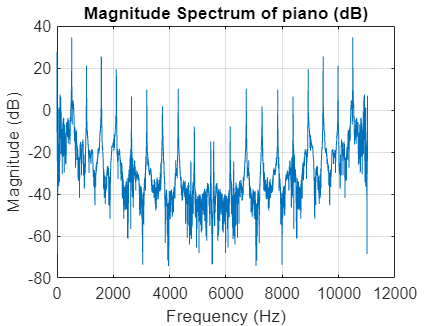



magnitude_dB = 20 * log10(magnitude);
plot(frequencies, magnitude_dB);
title('Magnitude Spectrum of piano (dB)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

a = 1 + mod(256, 3);

% Load the audio file
[y, Fs] = audioread("trumpet2.wav");

N = length(y); % Length of the signal
Y = fft(y); % Compute the FFT
frequencies = Fs * ((0:N-1) / N); % Frequency axis

% Calculate the magnitude of the spectrum
magnitude = abs(Y);

% Find the index of the peak frequency (excluding DC component)
[~, idx] = max(magnitude(2:end));

% Find the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(idx);

% Display the fundamental frequency
fprintf('Fundamental Frequency: %.2f Hz\n', fundamental_frequency);

Fundamental Frequency: 1047.09 Hz


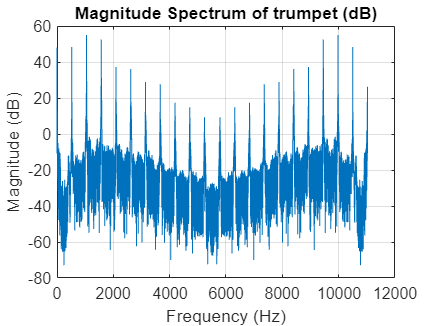



magnitude_dB = 20 * log10(magnitude);
plot(frequencies, magnitude_dB);
title('Magnitude Spectrum of trumpet (dB)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

a = 1 + mod(256, 3);

% Load the audio file
[y, Fs] = audioread("violin2.wav");

N = length(y); % Length of the signal
Y = fft(y); % Compute the FFT
frequencies = Fs * ((0:N-1) / N); % Frequency axis

% Calculate the magnitude of the spectrum
magnitude = abs(Y);

% Find the index of the peak frequency (excluding DC component)
[~, idx] = max(magnitude(2:end));

% Find the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(idx);

% Display the fundamental frequency
fprintf('Fundamental Frequency: %.2f Hz\n', fundamental_frequency);

Fundamental Frequency: 2368.84 Hz


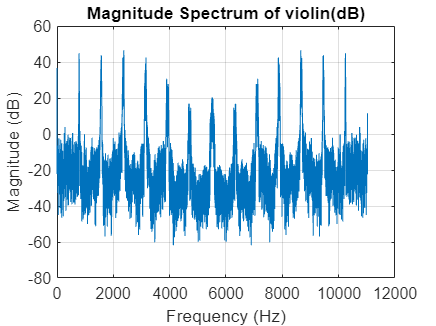



magnitude_dB = 20 * log10(magnitude);
plot(frequencies, magnitude_dB);
title('Magnitude Spectrum of violin(dB)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

[y1, Fs_1] = audioread("flute1.wav");
[y2, Fs_2] = audioread("flute2.wav");
[y3, Fs_3] = audioread("flute3.wav");
[y4, Fs_4] = audioread("flute4.wav");

N1 = length(y1);
N2 = length(y2);
N3 = length(y3);
N4 = length(y4);

% Compute the frequency axis based on the sampling rates
frequencies_1 = Fs_1 * ((0:N1-1) / N1);
frequencies_2 = Fs_2 * ((0:N2-1) / N2);
frequencies_3 = Fs_3 * ((0:N3-1) / N3);
frequencies_4 = Fs_4 * ((0:N4-1) / N4);

% Calculate the magnitude of the spectra
magnitude_1 = abs(fft(y1));
magnitude_2 = abs(fft(y2));
magnitude_3 = abs(fft(y3));
magnitude_4 = abs(fft(y4));

% Find the index of the peak frequency (excluding DC component)
[~, idx1] = max(magnitude_1(2:end));
[~, idx2] = max(magnitude_2(2:end));
[~, idx3] = max(magnitude_3(2:end));
[~, idx4] = max(magnitude_4(2:end));

% Calculate the corresponding fundamental frequencies (in Hz)
fundamental_frequency1 = frequencies_1(idx1 + 1);
fundamental_frequency2 = frequencies_2(idx2 + 1);
fundamental_frequency3 = frequencies_3(idx3 + 1);
fundamental_frequency4 = frequencies_4(idx4 + 1);

% Display the fundamental frequencies
fprintf('Fundamental Frequency 1: %.2f Hz\n', fundamental_frequency1);

Fundamental Frequency 1: 1063.20 Hz


fprintf('Fundamental Frequency 2: %.2f Hz\n', fundamental_frequency2);

Fundamental Frequency 2: 524.33 Hz


fprintf('Fundamental Frequency 3: %.2f Hz\n', fundamental_frequency3);

Fundamental Frequency 3: 793.50 Hz


fprintf('Fundamental Frequency 4: %.2f Hz\n', fundamental_frequency4);

Fundamental Frequency 4: 524.40 Hz




% Define flute recordings and their fundamental frequencies
flute_recordings = {'Flute 1', 'Flute 2', 'Flute 3', 'Flute 4'};
flute_frequencies = [fundamental_frequency1, fundamental_frequency2, fundamental_frequency3, fundamental_frequency4];

[y, Fs] = audioread("piano2.wav");

N = length(y); % Length of the signal
Y = fft(y); % Compute the FFT
frequencies = Fs * ((0:N-1) / N); % Frequency axis

% Calculate the magnitude of the spectrum
magnitude = abs(Y);

% Find the index of the peak frequency (excluding DC component)
[~, idx] = max(magnitude(2:end));

% Find the corresponding frequency value (in Hz)
fundamental_frequency = frequencies(idx);

% Display the fundamental frequency
fprintf('Fundamental Frequency: %.2f Hz\n', fundamental_frequency);

Fundamental Frequency: 523.06 Hz



% Calculate the differences between flute frequencies and piano frequency
differences = abs(flute_frequencies - fundamental_piano);

% Find the index of the minimum difference
[min_difference, min_idx] = min(differences);

% Determine which flute recording has the minimum difference
matching_flute = flute_recordings{min_idx};
matching_frequency = flute_frequencies(min_idx);

% Display the result
fprintf('(Recorded by %s)\n', matching_flute);

(Recorded by Flute 2)


fprintf('Matching Flute Frequency: %.2f Hz\n', matching_frequency);

Matching Flute Frequency: 524.33 Hz


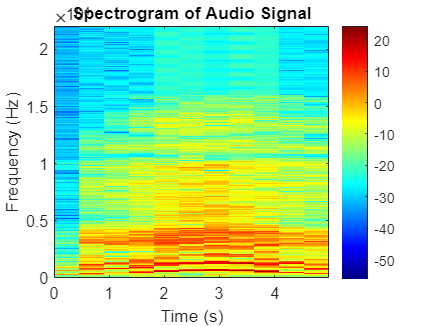


[y, Fs] = audioread("Opera.wav"); % Load the audio file
no_seg=10;
array=cell(1,no_seg);
length_seg=20000;  % Length of each segment
overlap=0;        % Overlap between segments
window=hamming(length_seg);

% Original Signal Spectrum
[mag,freq,t]= spectrogram(y,window,overlap,length(y),Fs);
figure;
imagesc(t, freq, 10*log10(abs(mag)));
axis xy;
colormap('jet');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Audio Signal');
colorbar;

start_index = 1

end_index = 22050

each_seg =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fundamental_frequency = -21136

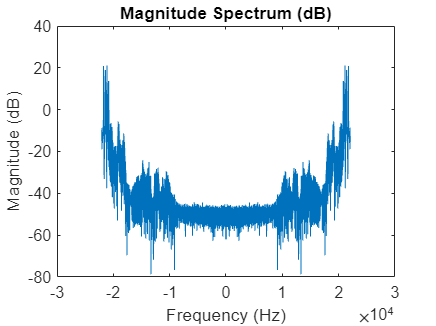

start_index = 22051

end_index = 44100

each_seg =     0.0069
    0.0088
    0.0111
    0.0134
    0.0152
    0.0161
    0.0163
    0.0161
    0.0155
    0.0143


fundamental_frequency = -21670

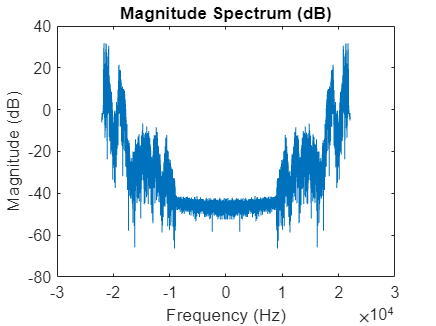

start_index = 44101

end_index = 66150

each_seg =    -0.0069
   -0.0133
   -0.0190
   -0.0232
   -0.0256
   -0.0266
   -0.0262
   -0.0239
   -0.0202
   -0.0167


fundamental_frequency = -21630

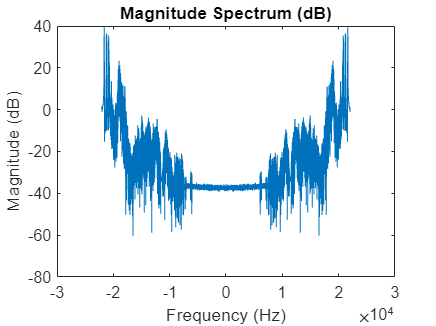

start_index = 66151

end_index = 88200

each_seg =     0.0233
    0.0244
    0.0289
    0.0367
    0.0448
    0.0509
    0.0560
    0.0600
    0.0599
    0.0554


fundamental_frequency = -21470

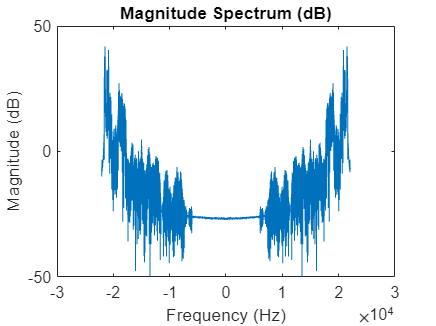

start_index = 88201

end_index = 110250

each_seg =    -0.0741
   -0.0839
   -0.0911
   -0.0966
   -0.1009
   -0.1006
   -0.0938
   -0.0838
   -0.0728
   -0.0594


fundamental_frequency = -21416

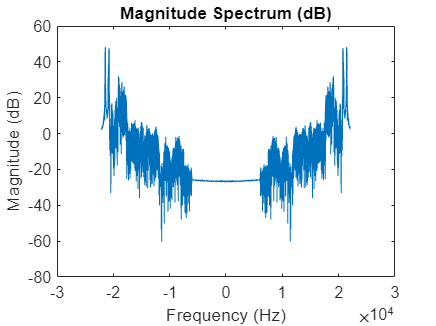

start_index = 110251

end_index = 132300

each_seg =     0.0284
    0.0335
    0.0318
    0.0247
    0.0154
    0.0031
   -0.0099
   -0.0200
   -0.0287
   -0.0363


fundamental_frequency = -21434

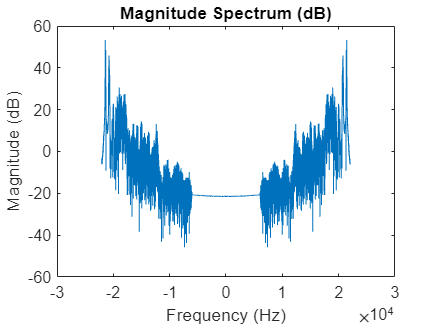

start_index = 132301

end_index = 154350

each_seg =    -0.1474
   -0.1551
   -0.1649
   -0.1760
   -0.1891
   -0.2019
   -0.2124
   -0.2184
   -0.2159
   -0.2059


fundamental_frequency = -21426

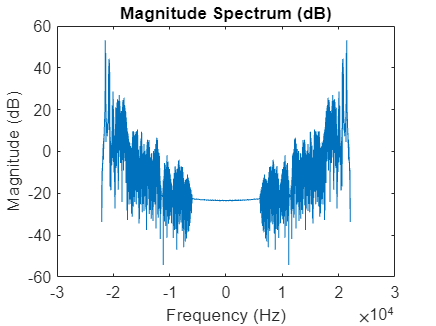

start_index = 154351

end_index = 176400

each_seg =    -0.0045
    0.0070
    0.0199
    0.0294
    0.0307
    0.0257
    0.0181
    0.0092
    0.0015
   -0.0018


fundamental_frequency = -20762

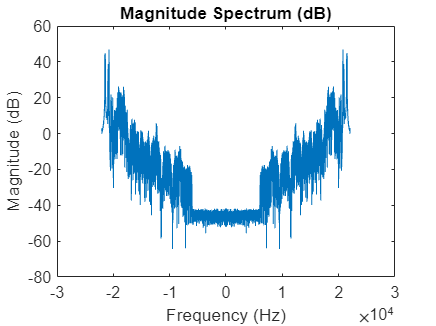

start_index = 176401

end_index = 198450

each_seg =    -0.0201
   -0.0199
   -0.0201
   -0.0228
   -0.0251
   -0.0256
   -0.0269
   -0.0265
   -0.0204
   -0.0119


fundamental_frequency = -21568

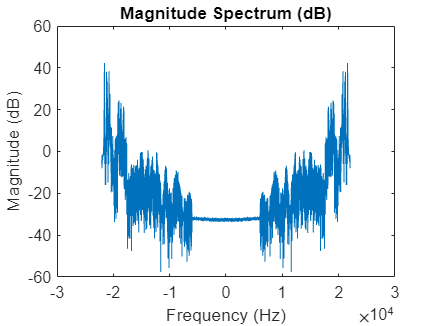

start_index = 198451

end_index = 220500

each_seg =     0.0251
    0.0218
    0.0186
    0.0141
    0.0077
    0.0025
   -0.0009
   -0.0043
   -0.0074
   -0.0110


fundamental_frequency = -21646

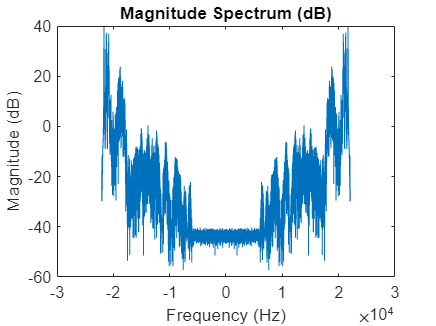



% Plotting the Spectrum for Each Segment
for i = 1:no_seg
    start_index=(i-1)*(length(y)/10)+1
    end_index=i*length(y)/10
    each_seg=y(start_index:end_index) % Extracting the audio Segment
    %each_seg=each_seg.*window; % Hamming
    % FFT of the segment
    fft_seg=fft(each_seg);
    % Mangnitude of the segment
    mag_seg=abs(fft_seg);
    array{i}=mag_seg;
    N=length(each_seg);
    frequencies = Fs * ((-N/2):(N/2-1)) / N;
    [~, idx_i] = max(mag_seg);
    fundamental_frequency = frequencies(idx_i)


    figure;
    plot(frequencies,20*log10(mag_seg))
    title('Magnitude Spectrum (dB)');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');

    
    


end

% Record a 3-second snippet of whistling
duration = 3;  % Duration in seconds

fs = 44100;    % Sampling frequency

recObj = audiorecorder(fs, 16, 1);
disp('Start whistling...');

Start whistling...


recordblocking(recObj, duration);
disp('End of recording.');

End of recording.



% Save the recorded audio as the reference
reference_audio = getaudiodata(recObj);
audiowrite('reference_whistle.wav', reference_audio, fs);

% Load the recorded whistling audio
[recorded_audio, fs_recorded] = audioread('reference_whistle.wav');

% Compute FFT of the recorded audio
fft_result = fft(recorded_audio);

% Calculate frequency bins
freq_bins = linspace(0, fs_recorded, length(fft_result));

% Calculate magnitude spectrum
magnitude_spectrum = abs(fft_result);

% Find peaks in the magnitude spectrum
[pks, peak_indices] = findpeaks(magnitude_spectrum);

% Plot the magnitude spectrum
figure;
plot(freq_bins, magnitude_spectrum);
hold on;
plot(freq_bins(peak_indices), pks, 'ro', 'MarkerSize', 8);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Recorded Whistling');
grid on;


% Find the highest peak frequency
[~, max_peak_index] = max(pks);
fundamental_frequency_recorded = freq_bins(peak_indices(max_peak_index));

fprintf('Fundamental Frequency of Recorded Whistling: %.2f Hz\n', fundamental_frequency_recorded);

Fundamental Frequency of Recorded Whistling: 214.33 Hz



% Test case 1: 
checkAccess();

Recording...
End of recording.
ACCESS DENIED



% Test case 2: 
checkAccess();

Recording...
End of recording.
ACCESS GRANTED


function checkAccess()
    fs = 44100;  % Sampling frequency
    
    % Record 3-second audio clip
    recObj = audiorecorder(fs, 16, 1);
    disp('Recording...');
    recordblocking(recObj, 3);
    disp('End of recording.');

    % Get the recorded audio
    recorded_audio = getaudiodata(recObj);

    
    % Calculate the fundamental frequency of the recorded audio
    fundamental_frequency_recorded = calculateFundamentalFrequency(recorded_audio, fs);
    
    % Load the reference audio
    [reference_audio, fs_ref] = audioread('reference_whistle.wav');
    
    % Calculate the fundamental frequency of the reference audio
    fundamental_frequency_reference = calculateFundamentalFrequency(reference_audio, fs_ref);
    
    % Define the error tolerance (5%)
    error_tolerance = 0.05 * fundamental_frequency_reference;

    
    % Compare the fundamental frequencies and provide access status
    if abs(fundamental_frequency_recorded - fundamental_frequency_reference) <= error_tolerance
        disp('ACCESS GRANTED');
        plotSpectrum(recorded_audio, fs, 'Test Audio (Access Granted)');
    else
        disp('ACCESS DENIED');
        plotSpectrum(recorded_audio, fs, 'Test Audio (Access Denied)');
    end
end

function fundamental_frequency = calculateFundamentalFrequency(audio, fs)
    % Compute FFT
    fft_result = fft(audio);
    
    % Calculate frequency bins
    freq_bins = linspace(0, fs, length(fft_result));
    
    % Calculate magnitude spectrum
    magnitude_spectrum = abs(fft_result);
    
    % Find peaks in the magnitude spectrum
    [~, peak_indices] = findpeaks(magnitude_spectrum);
    
    % Find the highest peak frequency
    [~, max_peak_index] = max(magnitude_spectrum(peak_indices));
    fundamental_frequency = freq_bins(peak_indices(max_peak_index));
end

function plotSpectrum(audio, fs, titleText)
    % Compute FFT of the audio
    fft_result = fft(audio);
    
    % Calculate frequency bins
    freq_bins = linspace(0, fs, length(fft_result));
    
    % Calculate magnitude spectrum
    magnitude_spectrum = abs(fft_result);
    
    % Find peaks in the magnitude spectrum
    [pks, peak_indices] = findpeaks(magnitude_spectrum);
    
    % Plot the magnitude spectrum
    figure;
    plot(freq_bins, magnitude_spectrum);
    hold on;
    plot(freq_bins(peak_indices), pks, 'ro', 'MarkerSize', 8);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(titleText);
    grid on;
end


